Pipeline to do a reaction knockout experiment

use the data file **dat9_biomass** for all records of biomass growth without media logs (this is *much *faster)

The reactions that showed increased growth at timestep=1h DID NOT show the same result at ts=0.9h. Conclusion: numerical instability bug.

%Generate/load the data
if ~exist('remcfg','var')
    load remoteconfig;
end

%reduce initial cellulose to reflect incomplete conversion
args.p9.v.initcellulose = args.default.v.initcellulose * 0.27;

args.p9.variableInitEnzyme = true;
args.p9.enzInMaint = false;
args.p9.v.addEnzymeToMaint = args.p9.enzInMaint;
v_default.addEnzymeToMaint = args.p9.enzInMaint;
args.p9.v.maintRxnAsObjective = false;

args.p9.v.maxcycles = 200;

args.p9.v.alpha = 0.0062;
args.p9.v.km_cel = 0.0909;
args.p9.v.kcat_cel = 45.2924;

args.p9.v_default = args.p9;

%designate a range of reactions to knock out (inclusive)
args.p9.lowerIdx = 1;
args.p9.upperIdx = 3951;
args.p9.mode = 'range'; %run all values between lowerIdx and upperIdx

%args.p9.mode = 'set'; %iterate over the given list of idxs
%args.p9.idxSet = [65 92 110 126 140 177 221 260 308 333 356 387 422 445 473 496];
%args.p9.idxSet = [1834 2920 2924 3427];
args.p9.idxSet = [2537 2986];
args.p9.idxSet = [27 335 336 2572 2677 2894]; %erroneous DFBA growth with 0 objflux. 
args.p9.idxSet = 300:399;
args.p9.idxSet = 2526; %'adenosine 3',5'-bisphosphate transport' got suspiciously high growth
args.p9.idxSet = 2344; %checking a sim that had growth despite no biomass rxn flux

args.p9.recordMedia = true;
args.p9.recordMedia = false;

args.p9.disableUptakeOnlyForExch = true;

%check for instability: run with a different timestep length
tsFactor = 1;
%tsFactor = .9;
args.p9.v.timestep = args.default.v.timestep * tsFactor;
args.p9.v.maxcycles = ceil(args.default.v.maxcycles / tsFactor);

args.p9.v.maxcycles = args.p9.v.maxcycles * 2;


if runPart9
    layouts9 = part9_generation_remote(args.p9);
    [layouts9,remcfg] = runCometsRemotely(layouts9,remcfg);
else
    if ~exist('dat9','var')
        load([datadir '\dat9.mat']);
    end
end

produce_enzyme	100 Ala-tRNA(Ala) [cytoplasm] + 37 Arg-tRNA(Arg) [cytoplasm] + 94 Asn-tRNA(Asn) [cytoplasm] + 73 Asp-tRNA(Asp) [cytoplasm] + 10680 atp[c] + 30 Cys-tRNA(Cys) [cytoplasm] + 55 Gln-tRNA(Gln) [cytoplasm] + 65 Glu-tRNA(Glu) [cytoplasm] + 124 Gly-tRNA(Gly) [cytoplasm] + 5340 gtp[c] + 18 His-tRNA(His) [cytoplasm] + 52 Ile-tRNA(Ile) [cytoplasm] + 98 Leu-tRNA(Leu) [cytoplasm] + 51 Lys-tRNA(Lys) [cytoplasm] + 22 Met-tRNA(Met) [cytoplasm] + 42 Phe-tRNA(Phe) [cytoplasm] + 75 Pro-tRNA(Pro) [cytoplasm] + 119 Ser-tRNA(Ser) [cytoplasm] + 107 Thr-tRNA(Thr) [cytoplasm] + 21 Trp-tRNA(Trp) [cytoplasm] + 67 Tyr-tRNA(Tyr) [cytoplasm] + 85 Val-tRNA(Val) [cytoplasm] 	->	10680 adp[c] + 5340 gdp[c] + 100 tRNA(Ala) [cytoplasm] + 37 tRNA(Arg) [cytoplasm] + 94 tRNA(Asn) [cytoplasm] + 73 tRNA(Asp) [cytoplasm] + 30 tRNA(Cys) [cytoplasm] + 55 tRNA(Gln) [cytoplasm] + 65 tRNA(Glu) [cytoplasm] + 124 tRNA(Gly) [cytoplasm] + 18 tRNA(His) [cytoplasm] + 52 tRNA(Ile) [cytoplasm] + 98 tRNA(Leu) [cytoplasm] + 51


if ~exist('model','var')
    model_default = load('C:\sync\biomes\models\yeastGEM_8.3.2.mat');
    model = model_default.model;
    model = prepareYeastGEMModel(model,args.p9.v);
end

if ~exist('dat9','var')
    dat9 = part9_parseRemoteResults(layouts9,remcfg.batchnum);
    %layouts9 = dat9.layout;
    [nrows,~] = size(dat9);
    dat9.layout = cell(nrows,1);
    dat9.enzymeInMaint = repmat(args.p9.v.addEnzymeToMaint,nrows,1);
    dat9.variableInitEnzyme = repmat(args.p9.variableInitEnzyme,nrows,1);
    dat9.maintRxnAsObjective = repmat(args.p9.v.maintRxnAsObjective,nrows,1);
    for i = 1:nrows
        ki = dat9.knockoutIdx(i);
        if ki > 0
            dat9.rxn(i) = model.rxns(ki);
            dat9.rxnName(i) = model.rxnNames(ki);
        else
            dat9.rxn(i) = {'none'};
            dat9.rxnName(i) = {'none'};
        end
    end
end

%find the objective flux for each knockout model
if ~ismember('objFlux',fields(dat9))
    [nrows,~] = size(dat9);
    dat9.objFlux = zeros(nrows,1);
    dat9.growthFlux = zeros(nrows,1);
    dat9.maintFlux = zeros(nrows,1);
    dat9.optStat = cell(nrows,1);
    optModels = cell(nrows,1);
    for i = 1:nrows
        %turn off uptake for anything not in the media
        layout = layouts9{i};
        imetnames = layout.mets(layout.media_amt > 0);
        imetnames = [{'glc-D[e]'}; imetnames];
        imetidxs = ismember(layout.models{1}.mets,imetnames);
        absentmets = ~imetidxs;
        exchrxns = find(findExchRxns(layout.models{1}));
        for j = 1:length(absentmets)
            if absentmets(j)
                rxns = find(layout.models{1}.S(j,:));
                exchrxn = rxns(find(ismember(rxns,exchrxns)));
                if any(exchrxn)
                    layout.models{1}.lb(exchrxn) = 0;
                end
            end
        end
        opt = optimizeCbModel(layout.models{1});
        opt.model = layout.models{1};
        optModels{i} = opt;
        dat9.objFlux(i) = opt.f;
        dat9.growthFlux(i) = opt.x(stridx('growth',model.rxnNames,false));
        dat9.maintFlux(i) = opt.x(stridx('non-growth associated maintenance reaction',model.rxnNames,false));
        dat9.optStat{i} = opt.origStat;
    end
end

Index exceeds the number of array elements (0).

%details for the baseline
baseline = dat9(dat9.knockoutIdx == 0,:);
b0 = baseline.biomass_max(1) %0.0207g

b0 = 0.0207

threshold = 0.001; %how close are we calling a match?

%did all runs complete?
dat9.run_complete = cellfun(@(x) x(end) < 0.000001,dat9.biomass_delta);
[nrows,~] = size(dat9);
disp(['All runs complete: ' string(sum(dat9.run_complete) == nrows)])

    "All runs complete: "    "true"


%load a layout/model to examine the enhanced phenotypes
load('C:\sync\biomes\cellulose\optima\clean_version\data\pipeline10_diagnosis\layout_noKO.mat');
baseline.model = layout.models{1};
baseline.layout = layout;

%turn off uptake for anything not in the media
imetnames = baseline.layout.mets(baseline.layout.media_amt > 0);
imetnames = [{'glc-D[e]'}; imetnames];
imetidxs = ismember(baseline.model.mets,imetnames);
absentmets = ~imetidxs;
exchrxns = find(findExchRxns(baseline.model));
for i = 1:length(absentmets)
    if absentmets(i)
        rxns = find(baseline.model.S(i,:));
        exchrxn = rxns(find(ismember(rxns,exchrxns)));
        if any(exchrxn)
            baseline.model.lb(exchrxn) = 0;
            %baseline.model.ub(exchrxn) = 0;
        end
    end
end

baseline.layout.models{1} = baseline.model;
baseline.opt = optimizeCbModel(baseline.model);
baseline.opt

ans = struct with fields:
         full: [3951×1 double]
          obj: 0.2890
        rcost: [3951×1 double]
         dual: [2685×1 double]
        slack: [2685×1 double]
       solver: 'gurobi'
    algorithm: 'default'
         stat: 1
     origStat: 'OPTIMAL'
         time: 0.1170
        basis: [1×1 struct]
            f: 0.2890
            x: [3951×1 double]
            v: [3951×1 double]
            w: [3951×1 double]
            y: [2685×1 double]
            s: [2685×1 double]

%remove exchange reactions. They're redundant when the model also includes
%uptake/secretion reactions
exchanges = findExchRxns(baseline.model);
nonexchanges = zeros(size(dat9,1),1);
for i = 1:size(dat9,1)
    if dat9.knockoutIdx(i) == 0
        nonexchanges(i) = 1;
    else
        nonexchanges(i) = ~exchanges(dat9.knockoutIdx(i));
    end
end
dat9_backup = dat9;
dat9 = dat9(logical(nonexchanges),:);

%histogram of yields
%dat9.biomass_max = cellfun(@(x) x(end),dat9.biomass);
n = hist(dat9.biomass_max)

n =          214           3           0           2           0           0           1           3          14        3474


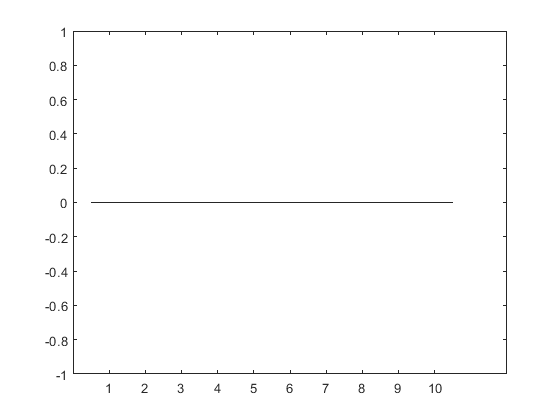

high = dat9(dat9.biomass_max > b0 + threshold,:);
low = dat9(dat9.biomass_max <= b0 + threshold,:);
hist(high.biomass_max);

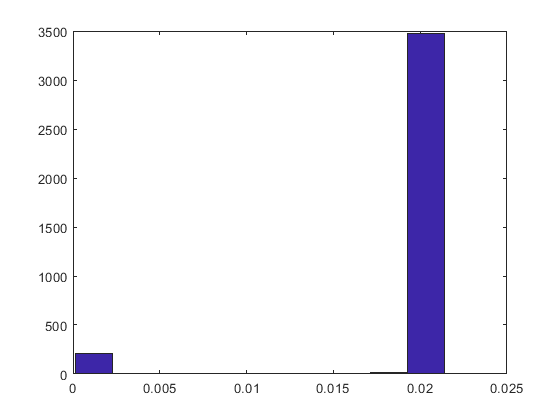

hist(low.biomass_max);

%examine the models that improved growth
ht = table();
ht.rxnIdx = high.knockoutIdx;
ht.rxn = high.rxn;
ht.rxnName = high.rxnName;
ht.biomass_max = high.biomass_max;
ht.objFlux = high.objFlux

ht =
  0×5 empty table


Compare objectives and yields

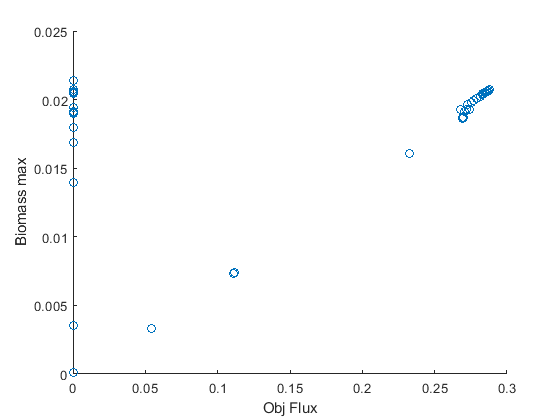

scatter(dat9.objFlux,dat9.biomass_max)
xlabel('Obj Flux');
ylabel('Biomass max');

rho_o = corr(dat9.objFlux,dat9.biomass_max)

rho_o = 0.2536

%ISSUE: SOME MODELS WITH EXPECTED FLUX OF 0 STILL GREW?

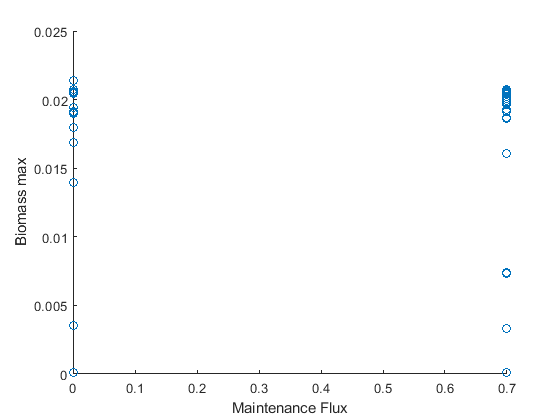

scatter(dat9.maintFlux,dat9.biomass_max)
xlabel('Maintenance Flux');
ylabel('Biomass max');

rho_m = corr(dat9.maintFlux,dat9.biomass_max)

rho_m = -0.1130

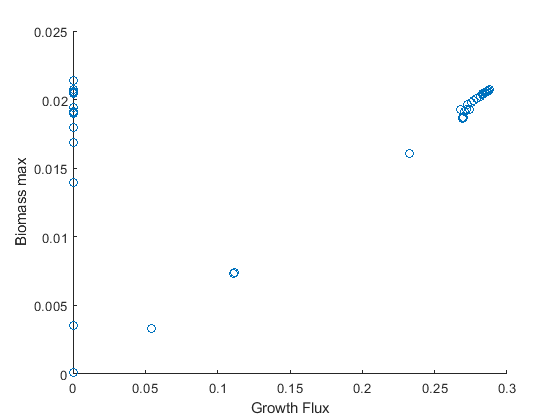

scatter(dat9.growthFlux,dat9.biomass_max)
xlabel('Growth Flux');
ylabel('Biomass max');

rho_g = corr(dat9.growthFlux,dat9.biomass_max)

rho_g = 0.2536

Diagnosing models with weird flux that still grew

Hypothesis: This is happening because of the modification to the models that changes the maintenance reaction from a hard limit (lb > 0) to a soft limit (primary objective function is to maximize maint, secondary objective is to grow). So these models can't satisfy the maintenance reqs but can satisfy the growth reqs.

errObj = dat9(dat9.objFlux==0,:);
errObj = errObj(errObj.biomass_max > .003,:);
errGrow = dat9(dat9.growthFlux==0,:);
errGrow = errGrow(errGrow.biomass_max > .003,:);